## Exercise 5.2)

#### *a)*

Problem Formulation

#### *b)*

clear;
load data.mat
x = sdpvar(1,8);
S = length(data.f(1,1,:));
alpha = 0.05;
p = zeros(S,1);
p(:) = 1/S;
lambda = 0.2;
R = sdpvar(S,1);
z = sdpvar(S,1);
I = find(cumsum(p,1)>=alpha,1);
t = R(I); %Is it I or I-1??

Cons = []; 
Cons = [Cons, x * data.c == 50];
Cons = [Cons, x >= 0];
for s=1:S
    Cons = [Cons, x * (sum(data.f(:,:,s).*data.pD(:,s)-(data.f(:,:,s)-data.q(:,:,s)).*data.pI(:,s),1)'-data.pA) == R(s)];
    Cons = [Cons, z(s) >= 0];
    Cons = [Cons, z(s) >= t - R(s)];
end

CVaR = t - (sum(z.*p,1)/alpha);
Obj = lambda * (x * data.E) + (1-lambda)* CVaR;
%Obj = lambda * mean(R) + (1-lambda)* CVaR;

Ops = sdpsettings ('solver','gurobi', 'verbose', 1);


Result = optimize(Cons, -Obj, Ops);

Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 309 rows, 208 columns and 1314 nonzeros
Model fingerprint: 0x965dd9c9
Coefficient statistics:
  Matrix range     [8e-02, 1e+04]
  Objective range  [2e-01, 2e+02]
  Bounds range     [0e+00, 0e+00]
  RHS range        [5e+01, 5e+01]
Presolve removed 208 rows and 100 columns
Presolve time: 0.03s
Presolved: 101 rows, 108 columns, 1007 nonzeros

Iteration    Objective       Primal Inf.    Dual Inf.      Time
       0      handle free variables                          0s
      36    2.6496221e+05   0.000000e+00   0.000000e+00      0s

Solved in 36 iterations and 0.03 seconds
Optimal objective  2.649622150e+05


value(Obj)

ans = -2.6496e+05

value(CVaR)

ans = -3.4402e+05

value(t)

ans = -3.1458e+05

#### *c)*

clear;
load data.mat
Revenues = [];
lambdas=[];
j = 0;
xVectors = zeros(8,10);
for lambda=0.01:0.1:0.99
j = j+1;
x = sdpvar(1,8);
S = length(data.f(1,1,:));
alpha = 0.05;
p = zeros(S,1);
p(:) = 1/S;
R = sdpvar(S,1);
z = sdpvar(S,1);
I = find(cumsum(p,1)>=alpha,1);
t = R(I); %Is it I or I-1??

Cons = []; 
Cons = [Cons, x * data.c == 50];
Cons = [Cons, x >= 0];
for s=1:S
    Cons = [Cons, x * (sum(data.f(:,:,s).*data.pD(:,s)-(data.f(:,:,s)-data.q(:,:,s)).*data.pI(:,s),1)'-data.pA) == R(s)];
    Cons = [Cons, z(s) >= 0];
    Cons = [Cons, z(s) >= t - R(s)];
end

CVaR = t - (sum(z.*p,1)/alpha);
Obj = lambda * (x * data.E) + (1-lambda)* CVaR;
%Obj = lambda * mean(R) + (1-lambda)* CVaR;

Ops = sdpsettings ('solver','gurobi', 'verbose', 0);


Result = optimize(Cons, -Obj, Ops);
Revenues = [Revenues, mean(value(R))];
lambdas = [lambdas, value(lambda)];
xVectors(:,j) = value(x)'; 
end

xVectors

xVectors =          0         0         0         0         0         0         0         0         0         0
   93.8882   92.7785   80.9801   80.9801   81.4224   78.5847    6.1474    6.0218         0         0
  154.2699  140.7849  128.0693  128.0693  121.3309  102.0736   44.8143   44.1087         0         0
  125.2027  135.7811  144.6905  144.6905  148.8844  164.4076  254.0617  254.6834  287.5595  162.7952
    7.3894   21.4966   23.2984   23.2984   22.2897   21.8834   51.1202   51.1424   49.1130   21.2228
   13.1185    3.1918         0         0         0         0         0         0         0         0
   62.0437   56.0595   62.2384   62.2384   64.5306   65.9907         0         0         0         0
         0    2.9131   11.9641   11.9641   12.6660   18.5417  113.9351  114.1195  139.3766  368.5959


test = xVectors(:,2)

test =          0
   92.7785
  140.7849
  135.7811
   21.4966
    3.1918
   56.0595
    2.9131


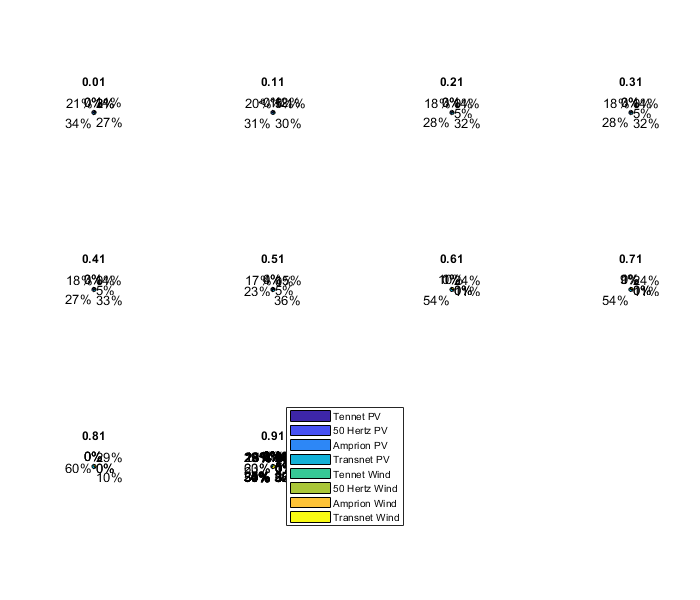

Labels = ["Tennet PV", "50 Hertz PV", "Amprion PV", "Transnet PV", "Tennet Wind", "50 Hertz Wind", "Amprion Wind", "Transnet Wind"];
%figure('Renderer', 'painters', 'Position', [10 10 700 600])
% t = tiledlayout(2,5,"TileSpacing","compact");
% 
% hold on
% for i = 1:length(xVectors)
%     ax = nexttile;
%     pie(ax,xVectors(:,i));
%     title(lambdas(i), " ");
% as
% end
% legend(Labels, 'Location','eastoutside', 'Orientation','vertical')
% %p = pie(xVectors(:,1));
% %legend(Labels, 'Location','eastoutside', 'Orientation','vertical')
% %hold on
% %for i = 2:length(xVectors)
%  %   pie(xVectors(:,i),Labels);
%  %end
%  hold off

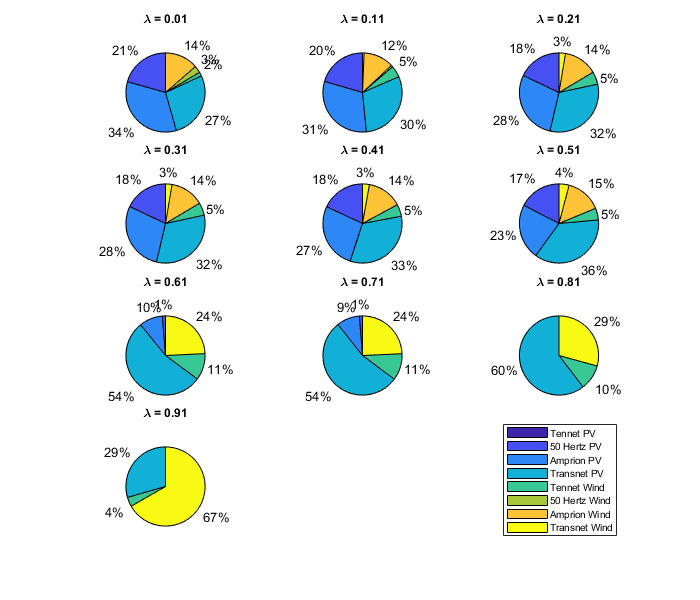


for i=1:length(xVectors)
 subplot(4,3,i)
 p = pie(xVectors(:,i));
 th = findobj(p,'Type','Text');
 isSmall = startsWith({th.String}, '<');
 isZero = startsWith({th.String}, '0');
 set(th(isZero), 'String', '');
 set(th(isSmall),'String', '');
 title("\lambda = " + lambdas(i), " ");
 end
hl = legend(Labels, 'Location','eastoutside', 'Orientation','vertical');
newPosition = [0.75 0.15 0.1 0.1];
newUnits = 'normalized';
set(hl,'Position', newPosition,'Units', newUnits)

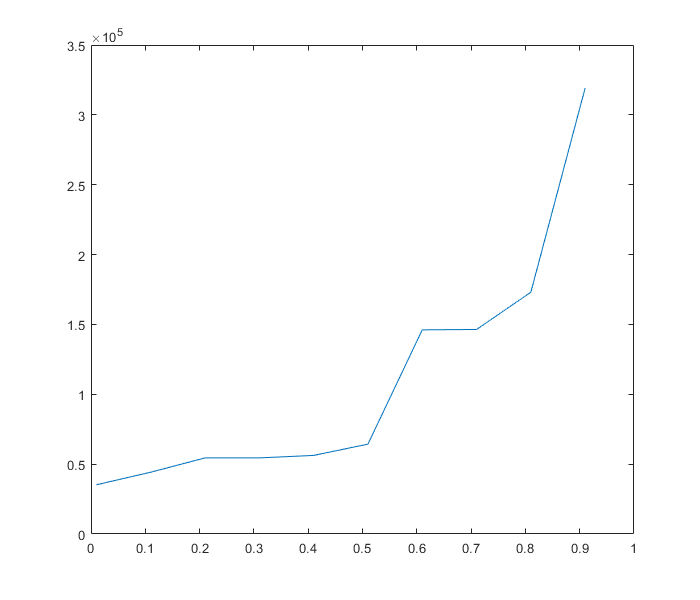

clf;
plot(lambdas,Revenues)

#### *d)*

## Exercise 5.3)